# **2. Line searches & functions of one variable**

- When it comes to minimising a function of several variables, we tend to use repeated minimisation of a function along search directions. In other words, minimising a multi-variable function involves repeated minimisation of the function for a single variable. We will look at this is more detail in due course.

- Nevertheless, the fact remains that the procedure of finding the minimum of functions of one variable is an important element in any optimisation method.

- We are now going to deal with such procedures in this section of the notes. In particular we are going to concentrate on two types of search methods – one based on fixed interval reductions (Grid, Fibonacci and Golden Section), the other based on curve fitting (Quadratic).

- Note that  these search methods are iterative approaches which continue until the minimum is found to be within the required degree of accuracy. ***As such, these methods***  ***are better suited for computer simulation!***

- This approach is useful in cases where:

- a mathematical expression for $F(x)$ is unknown

- calculating the solution of $\nabla$$F(x) = 0$ proves exceedingly difficult!

- In the case of (1) above, an example might be an industrial process that we do not have a mathematical expression for. However, we can still measure the output for given inputs by physically conducting the actual process itself.

- This example highlights one of the key features of a good optimisation algorithm. Running the industrial process is timely and expensive and therefore each time we want to see the effect of an input on the industrial process means extra cost for the company involved. 

- Clearly, therefore, ***a good optimisation is one that can converge on the minimum in the least possible number of function evaluations.***

- Finally, note that all these search methods assume that we can locate a range $[a\quad b]$ in which a single local minimum exists. In practice, how do we find such an interval?

### **Finding interval containing minimum**

- The first step is to calculate $F(x)$ at some point $x = k$. 

- We then need to find a point $b = k + h$, where h is a positive step. 

- If $F(k+h) > F(k)$, then we are moving away from the minimum and therefore, we now need to move in the opposite direction from $k$, i.e. we need to consider $F(k-h)$.

- If $F(k-h) > F(k)$, then we have found a bracketing interval $[k-h, k+h]$. 

- If not then we move further in the same direction, subtracting $2h$ each time we fail to establish an end for the bracketing interval, i.e. we consider $F(k-3h), F(k-7h)$, etc.

- If $F(k+h) < F(k),$ however, then we continue moving in the same direction and consider $F(k+3h), F(k+7h)$, etc… until we find a function value greater than $F(k+h)$.

- So, let us say that we find $F(k+3h) > F(k+h)$, then the bracketing interval is $[k,k+3h]$.

### 2.1 **The Grid method**

- This is the simplest method of determining the minimum of $F(x)$.

- We split the range $[a \quad b]$ into a number of subintervals of equal size. We then identify the subinterval which contains the minimum and repeat the process of subdividing.

- This process continues until we obtain a subinterval of suitable accuracy

#### Illustrative Example

- Consider the following function: $f(x) = x^3 – 12x$

- Given that a local minimum exists in the range $[0\quad 4]$, determine the value of this minimum with an error in this location of less than $0.001$.

- Let us take a grid with 8 divisions (arbitrarily chosen). The result of the first iteration is shown below:

clearvars
% Define the function
f=  @(x) x.^3 - 12*x

f = function_handle with value:
    @(x)x.^3-12*x


Define the range and grid divisions

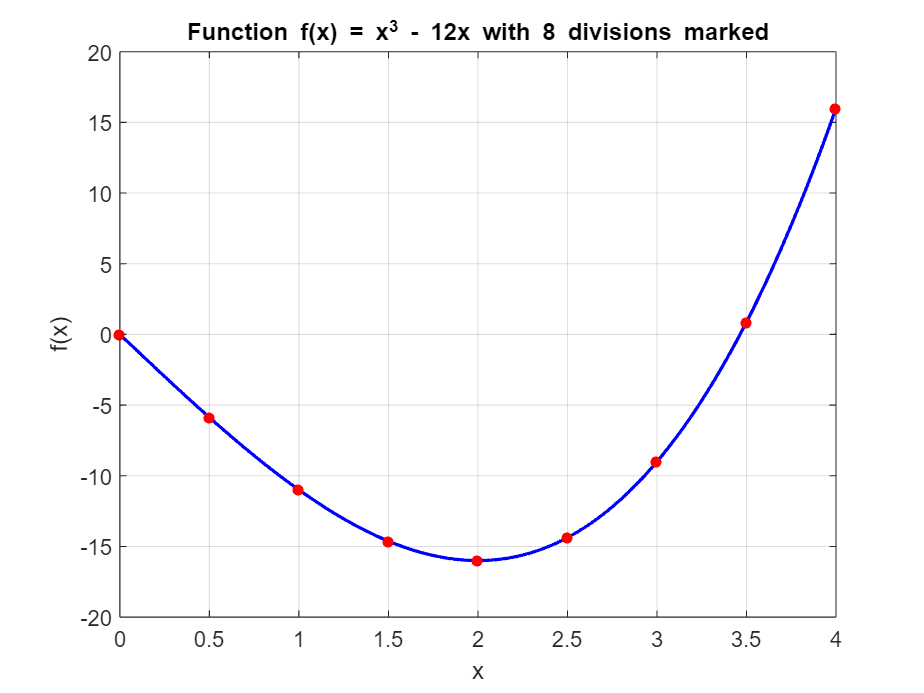

% Define the range and grid divisions
a= 0;
b= 4;
divisions=8;
step = (b-a)/divisions;

% Initialize variables for the minimum value and its location
min_val = Inf;
min_x = NaN;

% Grid search
for x = a:step:b
    current_val = f(x);
    if current_val < min_val
        min_val = current_val;
        min_x = x;
    end
end

% Plot the function
x_values = linspace(0, 4, 1000);
y_values = f(x_values);
figure;
plot(x_values, y_values, 'b-', 'LineWidth', 1.5); hold on;

% Mark the 8 divisions with red points
for x = a:step:b
    y_at_x = f(x);
    plot(x, y_at_x, 'r.','MarkerSize', 15);
end

xlabel('x');
ylabel('f(x)');
title('Function f(x) = x^3 - 12x with 8 divisions marked');
grid on;
hold off;

- Notice that the function has been divided into 8 subintervals. The function output is calculated at each one and the lowest one is determined. 

- In this case the function output at $x = 2$, i.e.  $f(2) = -16$, is the lowest obtained. Our new interval needs to bracket this value. Hence, we obtain the interval $[1.5 \quad 2.5]$. We know that this interval contains the local minimum.

- The size of this interval is 1 which is clearly greater than $0.001$, the acceptable error value, and therefore we need to continue.

- Change the intervals $a$ and $b$ in the code above.

- Now we see that the subinterval from the first iteration has been further subdivided. This leads to the new, even smaller, interval $[1.875\quad  2.125]$, which still gives a bound with an error greater than $0.001$.

Creating a code to calculate the interval

clearvars -except f
% Initial interval and grid divisions
a = 0;
b = 4;
divisions = 8;
step = (b-a)/divisions;

% Keep track of number of function evaluations
func_evals = 0;
iterations = 0;
% Iteratively refine the interval
while (b - a) > 0.001
    iterations = iterations + 1;

    min_val = Inf;
    min_x = NaN;
    
    % Evaluating function values over the subintervals
    for i = 0:divisions
        x = a + i * step;
        
        % Only evaluate function for new points
        if i > 0 && i < divisions
            func_evals = func_evals + 1;
            current_val = f(x);
            if current_val < min_val
                min_val = current_val;
                min_x = x;
            end
        end
    end
    
    % Refine the interval
    a = min_x - 1*step;
    b = min_x + 1*step;
    step = (b-a)/divisions;

    % Display the interval calculated at the current iteration
    fprintf('Iteration %d: Interval = [%f, %f]\n', iterations, a, b);
end

Iteration 1: Interval = [1.500000, 2.500000]
Iteration 2: Interval = [1.875000, 2.125000]
Iteration 3: Interval = [1.968750, 2.031250]
Iteration 4: Interval = [1.992188, 2.007812]
Iteration 5: Interval = [1.998047, 2.001953]
Iteration 6: Interval = [1.999512, 2.000488]



fprintf('The minimum lies in the interval [%f, %f]\n', a, b);

The minimum lies in the interval [1.999512, 2.000488]


fprintf('Total function evaluations: %d\n', func_evals);

Total function evaluations: 42


fprintf('Total iterations: %d\n', iterations);

Total iterations: 6


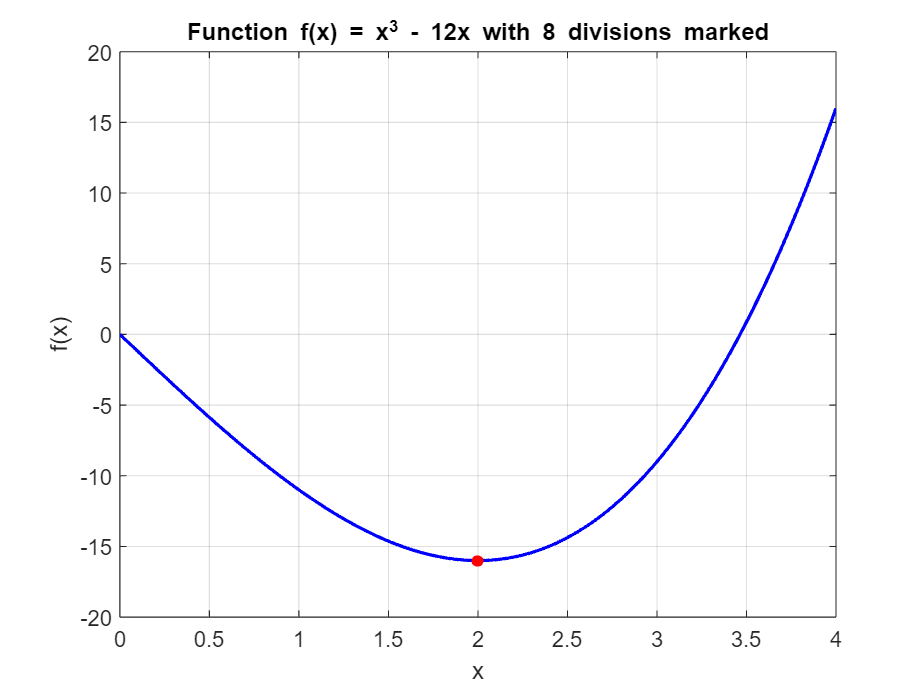


% Plot the function
x_values = linspace(0, 4, 1000);
y_values = f(x_values);
figure;
plot(x_values, y_values, 'b-', 'LineWidth', 1.5); hold on;

% Mark the 8 divisions with red points
for x = a:step:b
    y_at_x = f(x);
    plot(x, y_at_x, 'r.','MarkerSize', 15);
end

xlabel('x');
ylabel('f(x)');
title('Function f(x) = x^3 - 12x with 8 divisions marked');
grid on;
hold off;

- After 6 iterations we obtain the acceptable interval of $[1.9995\quad 2.0005]$. The actual minimum of 2 is clearly within this interval.

- This method guarantees that we reach the minimum (within an acceptable error limit). However, its downside is that it requires a lot of function evaluations in order to achieve the minimum. 

- In this example, we required 9 function evaluations on the first iteration, followed by 7 more per each iteration after this. Note, we do not need 9, as the outside two for each interval has already been evaluated on the previous iteration. Hence, in this case, we need 42 function evaluations in total.

- In order to improve on the efficiency of the grid method, we need to remove the restriction of dividing the original interval into equal size subintervals. This provides the motivation behind the Fibonacci and the Golden Section search methods.

### 2.2 **The Fibonacci search**

- Consider the case where we want to obtain the local minimum, i.e. an interval of suitable accuracy, and we have only n evaluations to do so. 

- Clearly it is unwise to use up all n evaluations on the first iteration. Instead, we should use the function evaluations we obtain on one iteration to determine the position of our next function evaluation. In order words, we learn information from one iteration and use this to improve our chances of locating the minimum on the next iteration.

- Now consider the following diagram:

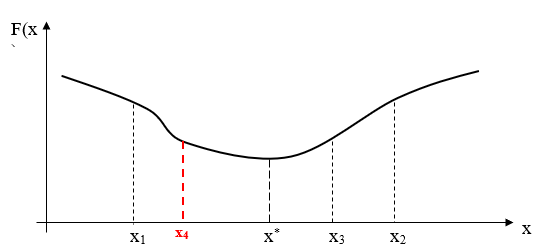

- Let us say that we know the minimum is located between the values $x_1$ and $x_2$ and that we know the value of $F(x_3)$ where $x_3$ lies in the range $[x_1 \quad x_2]$.

- If we were allowed to carry out one more function evaluation, where should we locate the point x4in order to obtain the smallest possible interval in which the minimum is certainly located?

- For convenience let $x_3– x_1 = L$ and $x_2 – x_4 = R$.

- Now consider the following two cases:

- if $F(x_4) < F(x_3)$ then the new interval for consideration will be $[x_1\quad x_3]$ of length $x_3 – x_1= L$

- if $F(x_4) > F(x_3)$ then the new interval for consideration will be $[x_4\quad x_2]$ of length $x_2– x_4 = R$

- Since we will not know in advance which of these two cases will occur, we choose the position of x4so as to minimise the larger of $L$ and $R$. 

- We achieve this by simply making $L = R$, i.e.: $x_3– x_1 = x_2 – x_4$  or   $x_4 = x_1+ (x_2 – x_3)$.

- Hence $x_4$ is place symmetrically in the interval with respect to $x_3$.

- Any other position of $x_4$ will result in either $L < R$ or $L > R$ and therefore can result in a new interval that is bigger than that obtained for $L = R$.

- We can now repeat this process for each new interval until we obtain an interval that bounds the minimum within a certain acceptable limit.

- So how do we determine the starting location for our first iteration? In other words how far from $x_1$ do we place $x_3$ (or, by symmetry, how far from $x_2$ do we place $x_4$)?

- In order to determine this we need to consider the end point and work backwards.

- Given that we want to obtain our local minimum with an error tolerance of less than e, we need to obtain its estimate at the centre of the interval $2\delta$ of size $2\varepsilon$ or less. Hence, our last useful interval can be represented as follows:

                             

- Working backwards gives us the following pattern:

                              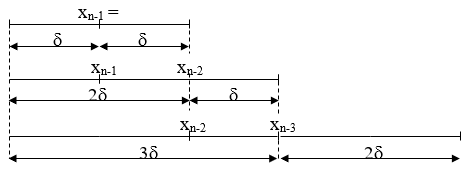

- This gives us the sequence $\delta$, $\delta$, 2$\delta$, 3$\delta$, 5$\delta$, 8$\delta$, etc. Here the interval $\delta$ is obtained from half the last useful interval.

- The reason why 2$\delta$ is the last useful interval is because $x_n= x_{n-1}$ and therefore no new information regarding the minimum is obtained. In other words, which half of this interval is the minimum if $F(x_n) = F(x_{n-1})$?

- This sequence is the same as the Fibonacci sequence (hence the name of the search method) which is defined by:

               $F_i = F_{i - 1} + F_{i – 2}$, with $F_0=F_1=1$               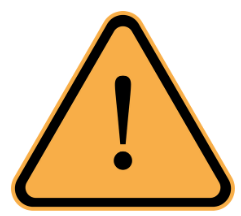 ***do not confuse the function notation ***$F_i(\cdot)$*** with the Fibonacci number ***$F_i$

- This gives the numbers: 1, 1, 2, 3, 5, 8, 13, 21, etc…

- Therefore, given an interval [a b] and a final one of size d, we can build the sequence: $\delta$, $\delta$, 2$\delta$, 3$\delta$, 5$\delta$, 8$\delta$,..., $F_i\delta$,...

- Letting $N$ be the number of iterations it takes to reduce the interval $[a\quad b]$ to the required interval $\delta$, we can make:

               
$$F_N\delta = b – a$$


- Hence $\delta = \frac{b-a}{F_N}$

- Thus, given a, b and e, we finally need to determine the smallest Fibonacci number that satisfies: $\delta\leq \varepsilon$

- The internal points are then obtained using the following relationships:

             $x_l = b - \delta F_{N-1}$   and   $x_r = a + \delta F_{N-1}$

             where $a$ and $b$ are the bounds of the current interval and $x_l$ and $x_r$ are the new internal subdivision points.

#### **Illustrative Example**

- The best way to understand the Fibonacci Search method is by carrying out an example.

- Once again consider the function:  $f(x) = x^3 – 12x$

- Given that a local minimum exists in the range $[0\quad 4]$, use the Fibonacci search method to determine the value of this minimum with an error in this location of less than $0.001$.

- Firstly, we need to determine the smallest Fibonacci number that satisfies $\delta\leq \varepsilon$:  $\delta = \frac{b-a}{F_N}=\frac{4}{F_N} \therefore F_N \geq \frac{4}{0.001}=4000$

- The smallest Fibonacci to satisfy this is $F_{18}= 4181$ which gives a value of $\delta = 0.0009567$.

- Noting that F_{N-1}= F_{17} = 2584, for our first iteration we locate: $x_1=b-\delta F_{N-1}$ and $x_2=a+\delta F_{N-1} \quad \therefore \quad x_1=b-2584\delta$ and $x_2=a+2584\delta$  

- This gives: $x_1 = 1.528$ and $x_2 = 2.472$ 

- These values are shown in the first iteration below, to check the graph choose *desired_iterations=* [1].

- Calculating the function at these new positions gives: $f(x_1)= -14.768$ and $f(x_2) = -14.557$

- Since $f(x_1)<f(x_2)$ our new interval is given by $[a\quad x_2]$ and contains the point $x_1$.

- Due to symmetry, the next point $x_3$ must satisfy, in this case, the following equation: $x_1 – a = x_2 – x_3$

- Therefore, for the second iteration: $x_3 = a + (x_2 – x_1)$ giving $x_3 = 0.944$. *Check in the code results the *$x_1$* for the second iteration. *

- Calculating the function at $x_3$ gives $f(x_3) = -10.489$. Clearly, $f(x_3) > f(x_1)$ and therefore our next interval is $[x_3 \quad x_2]$, containing $x_1$. 

- Remember, from one iteration to the next, we always make sure to bracket the minimum.

- Continuing in this manner, we eventually obtain the final interval (after 16 iterations) as [1.9986  2.0005]  

- Now, this interval is the last useful interval we obtain, and is equivalent to 2d.

- We take our estimate of the local minimum as the midpoint of the interval, i.e. 1.9995. Hence this has a maximum error value of  d = 0.0009567 (which is less than 0.001 as required).

- Note that this value is very close to the actual minimum of 2.

- The number of function evaluations required for this example is 4 for the first iteration plus 1 per each of the next 15 iterations, i.e. a total of 19 function evaluations.

clearvars
% Function definition
f=  @(x) x.^3 - 12*x

f = function_handle with value:
    @(x)x.^3-12*x


% Initial interval [a,b]
a=0;
b=4;

% Desired accuracy
epsilon=0.1;

% Compute the number of required Fibonacci numbers
n = 1;
while fibonacci(n+1) <= (b-a)/epsilon
    n = n + 1;
end

% Generate Fibonacci numbers
F = zeros(1, n+1);
F(1) = 1; F(2) = 1;
for i = 3:n+1
    F(i) = F(i-1) + F(i-2);
end

% Store x1 and x2 for plotting
x1_values = zeros(1, n-1);
x2_values = zeros(1, n-1);


% Main loop
for k = 1:n-1
    lambda = a + (F(n-k)/F(n-k+2))*(b-a);
    mu = a + (F(n-k+1)/F(n-k+2))*(b-a);
    
    x1_values(k) = lambda;
    x2_values(k) = mu;
   

    fprintf('Iteration %d: x1 = %2.6f, x2 = %f, f(x1) = %f, f(x2) = %f\n', k, lambda, mu, f(lambda), f(mu));
    
    if f(lambda) > f(mu)
        a = lambda;
    else
        b = mu;
    end
end

Iteration 1: x1 = 1.529412, x2 = 2.470588, f(x1) = -14.775494, f(x2) = -14.567067
Iteration 2: x1 = 0.941176, x2 = 1.529412, f(x1) = -10.460411, f(x2) = -14.775494
Iteration 3: x1 = 1.529412, x2 = 1.882353, f(x1) = -14.775494, f(x2) = -15.918583
Iteration 4: x1 = 1.882353, x2 = 2.117647, f(x1) = -15.918583, f(x2) = -15.915327
Iteration 5: x1 = 1.764706, x2 = 1.882353, f(x1) = -15.680847, f(x2) = -15.918583
Iteration 6: x1 = 1.882353, x2 = 2.000000, f(x1) = -15.918583, f(x2) = -16.000000
Iteration 7: x1 = 2.000000, x2 = 2.000000, f(x1) = -16.000000, f(x2) = -16.000000





% Plot the function and the x1, x2 values for desired iterations
x = linspace(0, 4, 1000);
y = f(x);
figure;
plot(x, y, 'b', 'LineWidth', 2);
hold on;

fprintf('Iteration you want to plot: i.e.: [1], [1,2]');

Iteration you want to plot: i.e.: [1], [1,2]

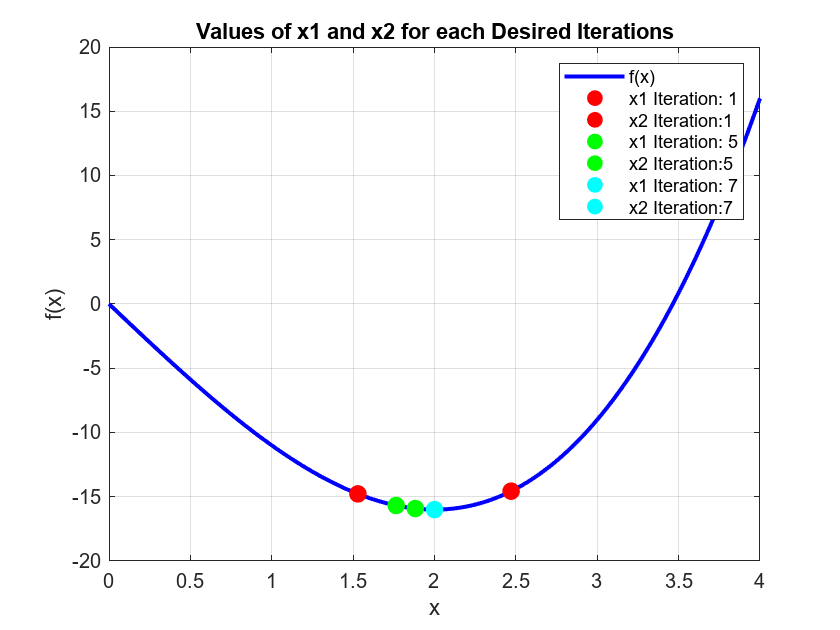

desired_iterations = [1,5,7];
colors = ['r', 'g', 'c', 'm'];
for i = 1:length(desired_iterations)
    iter = desired_iterations(i);
    plot(x1_values(iter), f(x1_values(iter)), '.','MarkerSize',30 ,'Color', colors(i));
    plot(x2_values(iter), f(x2_values(iter)), '.','MarkerSize',30, 'Color', colors(i));
end

% Create dynamic legend
legend_str = {'f(x)'};
for i = 1:length(desired_iterations)
    legend_str{end+1} = ['x1 Iteration: ' num2str(desired_iterations(i))];
    legend_str{end+1} = ['x2 Iteration:' num2str(desired_iterations(i))];
end

legend(legend_str);
xlabel('x');
ylabel('f(x)');
title('Values of x1 and x2 for each Desired Iterations');
grid on;

- The Fibonacci search method uses a fixed number of function evaluations to determine the position of the minimum within a given maximum error. 

- However, there are situations where the maximum error is not useful for obtaining the required precision – for example, we may require obtaining the position of the minimum correct to a given number of significant figures.

- Therefore, it’s not always possible to obtain in advance the number of function evaluations required. Unfortunately, this value is needed by the Fibonacci search method in order to determine the position of $x_1$ and $x_2$, that lead to the first subinterval.

- The Golden Section search method is a simple efficient alternative that provides the required property, i.e. it does not need to know the number of function evaluations in advance.

## **2.3 The Golden Section search**

- The Golden Section search is based on the same principles as the Fibonacci search. However it differs in the way in which the location of the intervals is chosen.

- In this case, the intervals are reduced at each iteration by the same factor, $\tau$. In order words:


$$\tau =\frac{F_{i-1} \delta }{F_i \delta }$$


             where $F_i \delta$ is the length of one interval and $F_{i-1} \delta$ is the length of the subsequent          reduced interval.

- Since $F_i =F_{i-1} +F_{i-2}$ (the Fibonacci sequence), we can state that:


$$F_N = F_{N-1} + F_{N-2}$$


-  Dividing across by $F_{N-1}$ gives:

 
$$\frac{F_N }{F_{N-1} }=1+\frac{F_{N-2} }{F_{N-1} }\;\;\;\;\;\;\;\;\;\;\;\Rightarrow \frac{1}{\tau }=1+\tau$$
                           

-  Multiplying across by $\tau$ gives:


$$1=\tau +\tau^2 \;\;\;\;\;\textrm{or}\;{\;\;\;\tau }^2 \;+\tau -1=0$$


- Solving this equation (and considering only the positive root) we obtain:


$$\tau =\;\frac{\left(-1+\sqrt{5}\right)}{2}\approx 0.6180339887$$


- This is known as the golden ratio, hence the name of the search method.

- So how do we determine the new positions $x_1$ and $x_2$ in the first interval $[a\quad b]$? 

- Refer to the following diagram. From symmetry we know that the reduced intervals equal each other, i.e.:


$$x_2 \;–\;a=b\;–\;x_1$$


- We now know that each of these distances have to be $\tau$ $(b – a)$, i.e. the golden ratio times the original interval length.

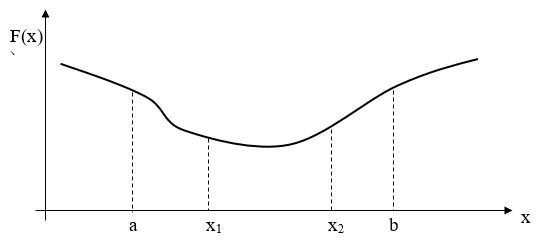

- Hence:           $x_2  – a = \tau (b – a)$   and   $b – x_1 = \tau (b – a)$

- This gives:              $x_2 = a + \tau (b – a)$   and   $x_1 = b - \tau(b – a)$

- These expressions are used for all subsequent intervals (with the appropriate substitutions – i.e. a and b are replaced with the new interval boundaries, etc…).

clearvars
% Function to be minimized
f = @(x) x.^3 - 12*x;
% Golden Section Search Parameters
a = 0; % Lower bound of the search interval
b = 4; % Upper bound of the search interval
tolerance = 0.001; % Tolerance for the error in the location of the minimum
tau = 0.618; % Approximate value of the golden ratio

% Initial calculations of x1 and x2
x1 = b - tau * (b - a);
x2 = a + tau * (b - a);

fprintf('Initial x1 = %.3f\n', x1);

Initial x1 = 1.528


fprintf('Initial x2 = %.3f\n', x2);

Initial x2 = 2.472


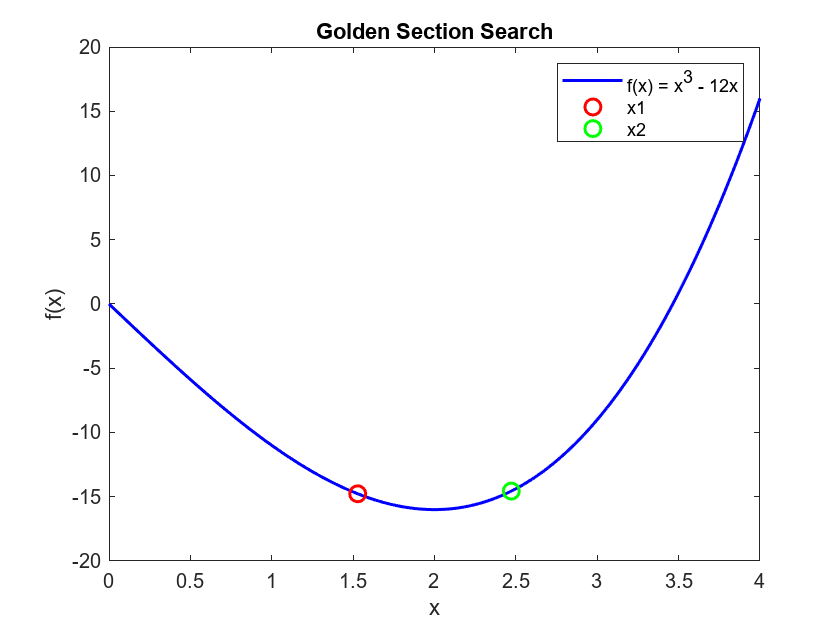


% Plot the function
x = linspace(a, b, 1000);
y = f(x);
figure;
plot(x, y, 'b', 'LineWidth', 1.5);
hold on;
plot(x1, f(x1), 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);
plot(x2, f(x2), 'go', 'MarkerSize', 8, 'LineWidth', 1.5);
legend('f(x) = x^3 - 12x', 'x1', 'x2');
xlabel('x');
ylabel('f(x)');
title('Golden Section Search');


% % Golden Section Search Algorithm
% while (b - a) > tolerance
%     if f(x1) < f(x2)
%         b = x2;
%         x2 = x1;
%         x1 = b - tau * (b - a);
%     else
%         a = x1;
%         x1 = x2;
%         x2 = a + tau * (b - a);
%     end
% end
% 
% % Display the result
% minimumValue = (a + b) / 2;
% fprintf('The local minimum occurs at x = %.4f\n', minimumValue);
%fprintf('The value of the function at this point is f(x) = %.4f\n', f(minimumValue));


% Calculate the function values at x1 and x2
f_x1 = f(x1);
f_x2 = f(x2);

fprintf('f(x1) = %.3f\n', f_x1);

f(x1) = -14.768


fprintf('f(x2) = %.3f\n', f_x2);

f(x2) = -14.558


% Since f(x1) < f(x2), update the interval to [a, x2]
if f(x1) < f(x2)
    b = x2;
    fprintf('New interval is [%.3f, %.3f]\n', a, b);
end

New interval is [0.000, 2.472]


% Initial calculations of x1 and x3
x1 = 1.528;
x3 = a + (b - x1); % Using the symmetry property

fprintf('x1 = %.3f, f(x1) = %.3f\n', x1, f(x1));

x1 = 1.528, f(x1) = -14.768


fprintf('x3 = %.3f, f(x3) = %.3f\n', x3, f(x3));

x3 = 0.944, f(x3) = -10.487


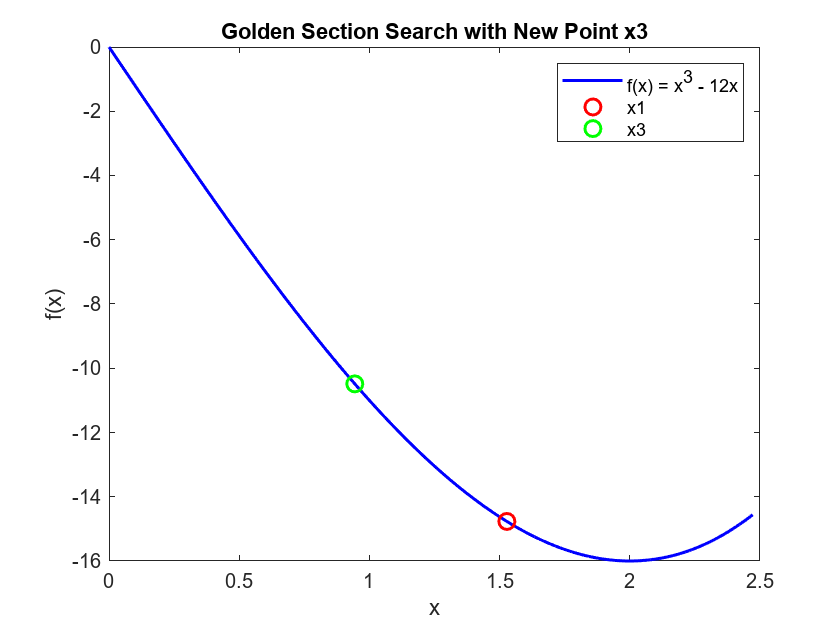


% Plot the function
x = linspace(a, b, 1000);
y = f(x);
figure;
plot(x, y, 'b', 'LineWidth', 1.5);
hold on;
plot(x1, f(x1), 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);
plot(x3, f(x3), 'go', 'MarkerSize', 8, 'LineWidth', 1.5);
legend('f(x) = x^3 - 12x', 'x1', 'x3');
xlabel('x');
ylabel('f(x)');
title('Golden Section Search with New Point x3');

% Function to be minimized
f = @(x) x.^3 - 12*x;

% Golden Section Search Parameters
a = 0; % Lower bound of the search interval
b = 4; % Upper bound of the search interval
tolerance = 0.001; % Tolerance for the error in the location of the minimum
tau = 0.618; % Approximate value of the golden ratio

% Golden Section Search Algorithm
iteration = 0;
while (b - a) > tolerance
    iteration = iteration + 1;
    x1 = b - tau * (b - a);
    x2 = a + tau * (b - a);
    
    if f(x1) < f(x2)
        b = x2;
    else
        a = x1;
    end
    
    if iteration == 16
        break;
    end
end

% Display the result after 16 iterations
fprintf('After 16 iterations, the interval is [%.4f, %.4f]\n', a, b);

After 16 iterations, the interval is [1.9996, 2.0014]


minimumValue = (a + b) / 2;
fprintf('The estimated minimum value x* = %.4f\n', minimumValue);

The estimated minimum value x* = 2.0005


fprintf('The value of the function at this point is f(x*) = %.4f\n', f(minimumValue));

The value of the function at this point is f(x*) = -16.0000


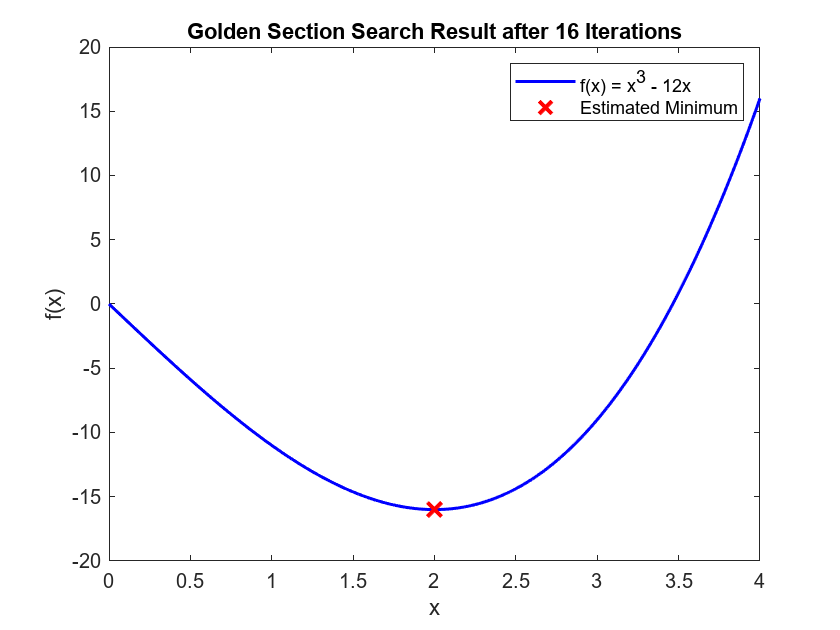


% Plot the function
x = linspace(0, 4, 1000);
y = f(x);
figure;
plot(x, y, 'b', 'LineWidth', 1.5);
hold on;
plot(minimumValue, f(minimumValue), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
legend('f(x) = x^3 - 12x', 'Estimated Minimum');
xlabel('x');
ylabel('f(x)');
title('Golden Section Search Result after 16 Iterations');

function num = fibonacci(n)
    if n <= 1
        num = 1;
    else
        num = fibonacci(n-1) + fibonacci(n-2);
    end
end